%% Aproximação de S em Z
freq = 60

freq = 60

N = 378.8;
D = [1 0 (120*pi)^2];
G = tf(N,D)


G =
 
      378.8
  --------------
  s^2 + 1.421e05
 
Continuous-time transfer function.



T = 0.2 * pi;
syms s z;
Gs = (378.8) / (s^2 + (120*pi)^2)

$$Gs = \frac{1894}{5\,\left(s^{2}+\frac{4883285160246119}{34359738368}\right)}$$

%Para o primeiro 
Gz1 = simplifyFraction(subs(Gs,s,((z-1)/T)))

$$Gz1 = \frac{65077344468992\,\pi^{2}}{5\,\left(858993459200\,z^{2}-1717986918400\,z+4883285160246119\,\pi^{2}+858993459200\right)}$$

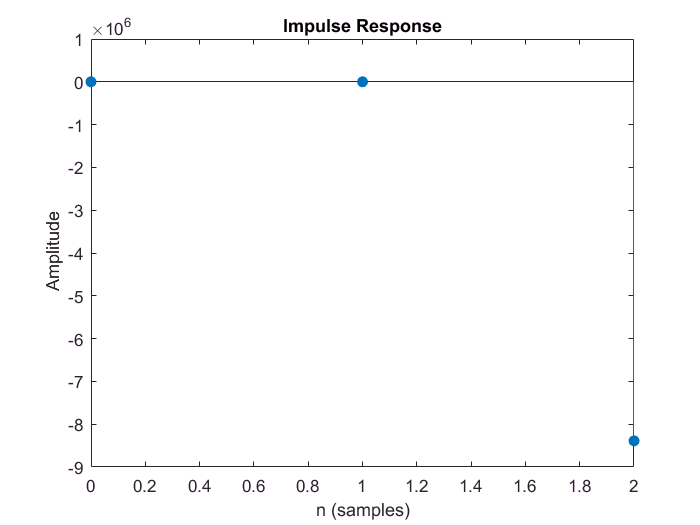

N1 = 65077344468992*pi^2;
D1 = [5*(858993459200) 5*(-1717986918400) 5*(4883285160246119*pi^2 + 858993459200)];
impz(N1,D1)

% Para o segundo 
Gz2 = simplifyFraction(subs(Gs,s,((z-1)/T*z)))

$$Gz2 = \frac{65077344468992\,\pi^{2}}{5\,\left(858993459200\,z^{4}-1717986918400\,z^{3}+858993459200\,z^{2}+4883285160246119\,\pi^{2}\right)}$$

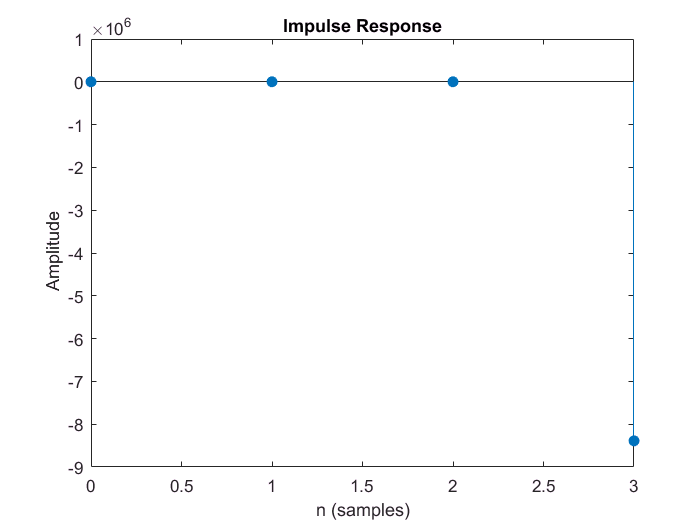

N2 = 65077344468992*pi^2;
D2 = [5*(858993459200) 5*(-1717986918400) 5*(858993459200) 5*(4883285160246119*pi^2)];
impz(N2,D2)

Gz3 = simplifyFraction(subs(Gs,s,((2/T)*((z-1)/(z+1)))))

$$Gz3 = \frac{600232559208066621608688967745536\,{\left(z+1\right)}^{2}}{5\,\left(45043566791483447984654961569229713\,z^{2}+90074289597040891553378356249897182\,z+45043566791483447984654961569229713\right)}$$

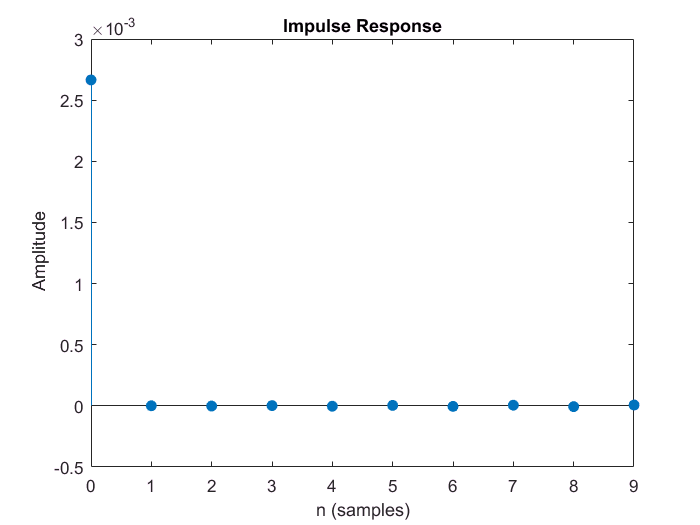

N3 = [600232559208066621608688967745536 2*600232559208066621608688967745536 600232559208066621608688967745536];
D3 = [5*45043566791483447984654961568229813 5*90074289597040891553378356249897182 5*45043566791483447984654961569229713];
impz(N3,D3)